clear;

Nvar = 2;
Nmax = 50;
errodf = 15e-3;
NPontosIniciais = 7;
x_values=[-11;-11]; y_values=[7;7];

PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
lambda = 0.0005;

## Teste 1

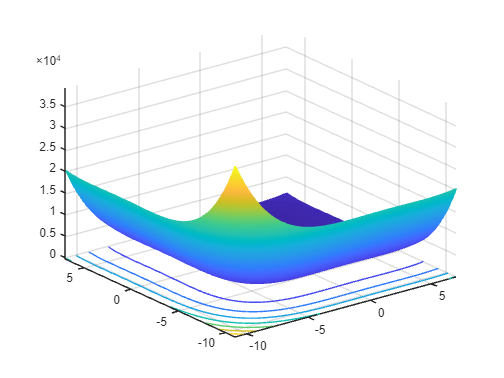

tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(g, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste1 = toc;
xopt_teste1 = minGlobal(Lopt, g);
taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit);
tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax);
[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g);
close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

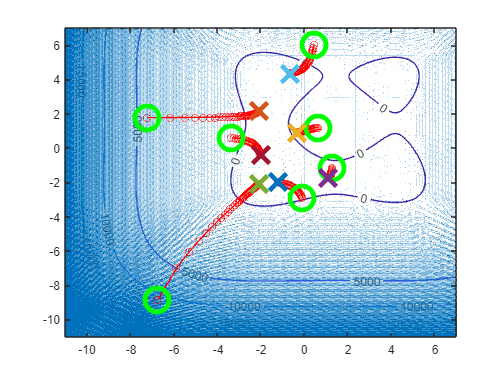


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2

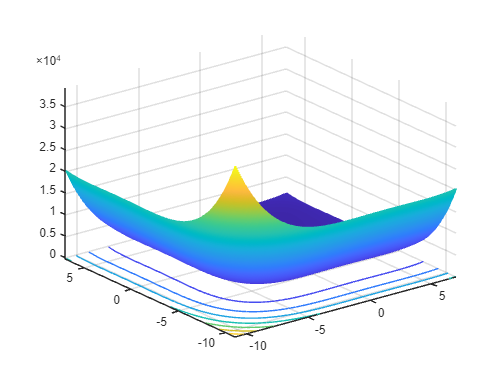

tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2 = toc;
xopt_teste2 = minGlobal(Lopt, g);
taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit);
tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax);
[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, g);
close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

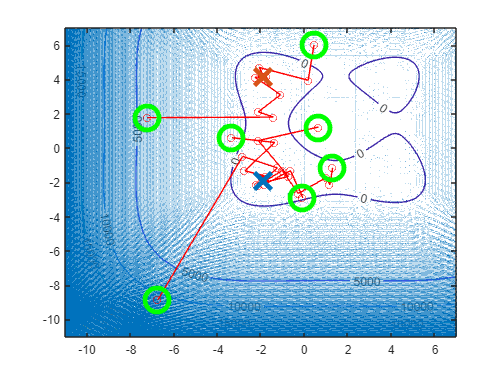


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3

tic;
[Lista, LNit, Lopt, dffinal] = newton_raphson(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3 = toc;
xopt_teste3 = minGlobal(Lopt, g);
taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit);
tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax);
[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, g);
close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

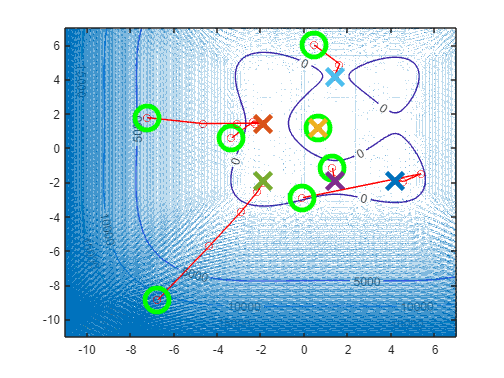


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off